clc;
clear;
close all;

% Value to be changed
dBTarget = -40;
p0 = ones(1,4);

OPTIMIZATION TASK

% Create optimization variables
p = optimvar("p",4,1,"LowerBound",1,"UpperBound",10);

% Set initial starting point for the solver
initialPoint.p = p0;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@SLL_error,p,dBTarget);

% Set nondefault solver options
options = optimoptions("ga","PlotFcn",["gaplotbestf","gaplotbestindiv"]);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       p

	minimize :
       SLL_error(p, (-40))


	variable bounds:
       1 <= p(1) <= 10
       1 <= p(2) <= 10
       1 <= p(3) <= 10
       1 <= p(4) <= 10




Solving problem using ga.
ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


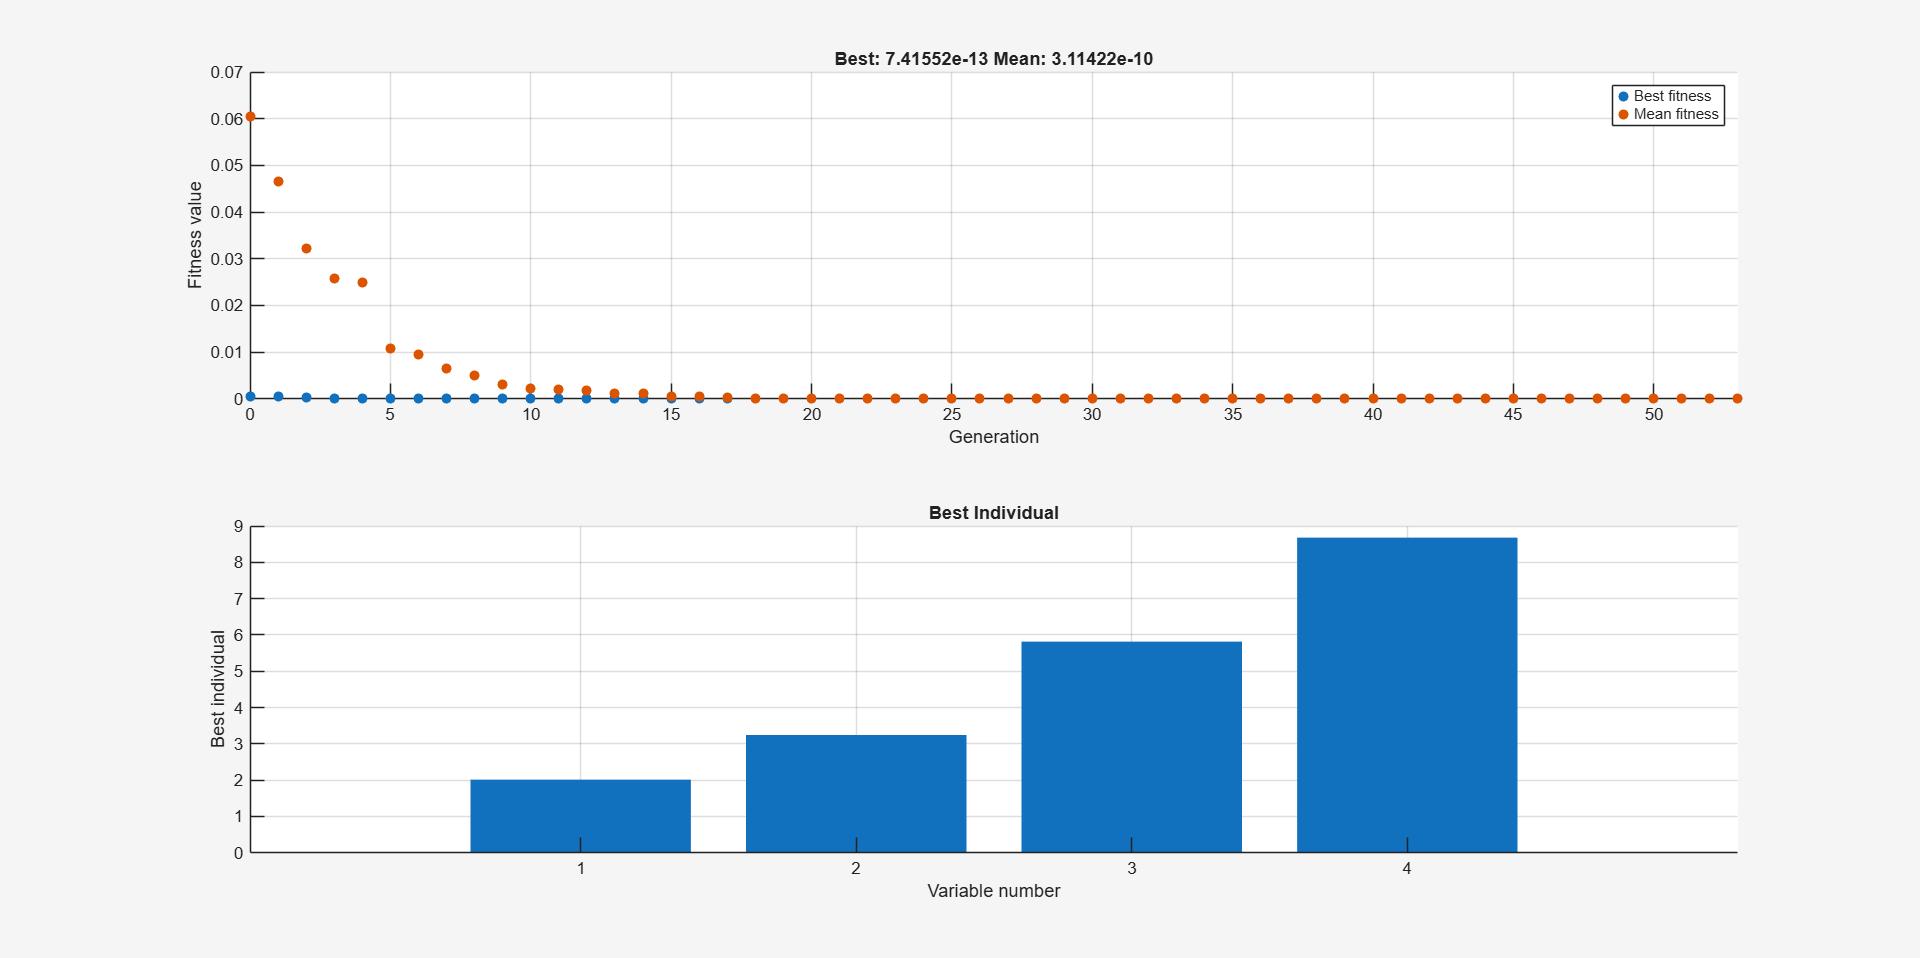


% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","ga","Options",options);


% Display results
solution

solution = struct with fields:
    p: [4×1 double]


reasonSolverStopped

reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue

objectiveValue = 7.4155e-13


% Clear variables
clearvars p initialPoint options reasonSolverStopped objectiveValue